## Delayed Lotka Volterra

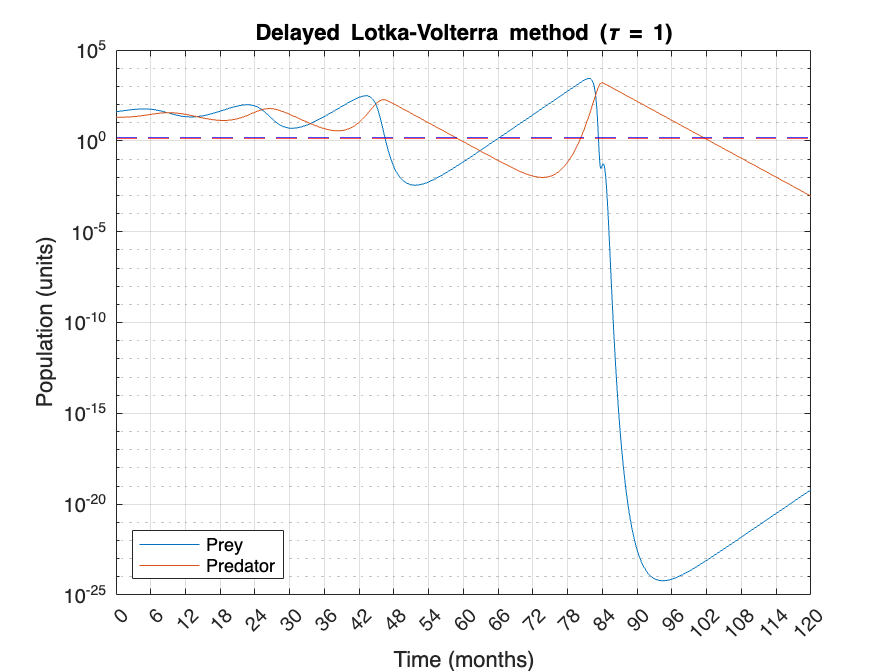

a = 0.5; b = 0.02; c = 0.01; d = 0.4;

prey = 40; predator = 20; n = 1000; t_end = 120; tau = 1;

f = DelayedLotkaVolterra(a,b,c,d);

phi = @(t) [prey; predator];

[t, x] = StepsMethod(f,0,t_end,@DormandPrince,tau,phi,n);

figure()
semilogy(t,x)
grid
yline(log10(d/c), "--",Color="b");
yline(log10(a/b), "--",Color="r");

legend("Prey","Predator",location="southwest")
title("Delayed Lotka-Volterra method (\tau = " + tau + ")")

xlim([0 t_end])

xticks(0:6:t_end)
ylabel("Population (units)")
xlabel("Time (months)")

It can be seen how where the logistic model remained stable, the standard Lotka Volterra, even for small delays, becomes chaotic and ultimately collapes. Increasing the delay leads usually to the explosion of the solution, due to numerical precision limits, even for high order methods (DOPRIS is being used). A semilogarithmic plot is used to show order of magnitude.

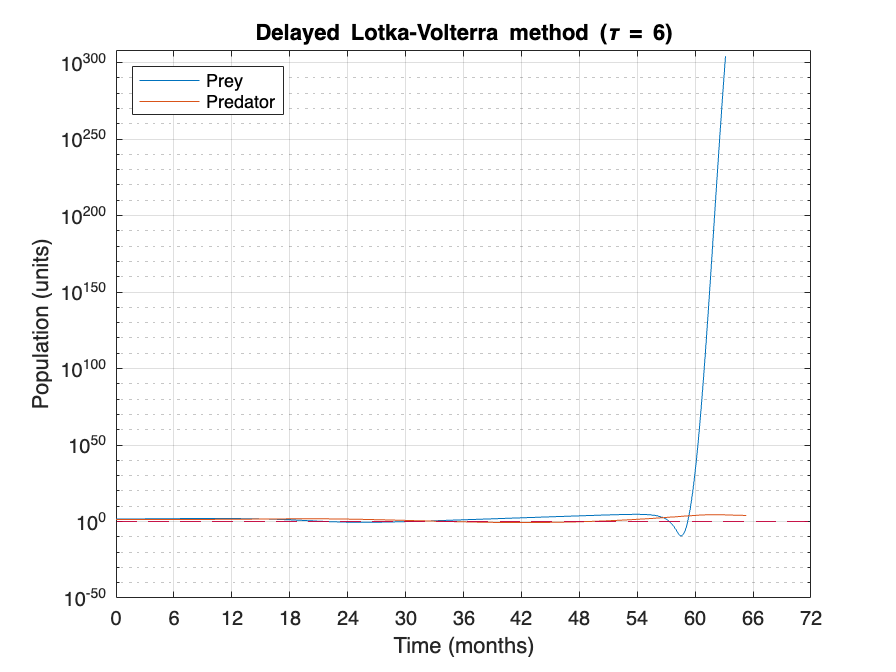

a = 0.5; b = 0.02; c = 0.01; d = 0.4;

prey = 40; predator = 20; n = 1000; t_end = 72; tau = 6;

f = DelayedLotkaVolterra(a,b,c,d);

phi = @(t) [prey; predator]+ 0.01*sin(t);

[t, x] = StepsMethod(f,0,t_end,@DormandPrince,tau,phi,n);

figure()
semilogy(t,max(x,0)) % Max is used to avoid negative data
grid
yline(log10(d/c), "--",Color="b");
yline(log10(a/b), "--",Color="r");

legend("Prey","Predator",location="northwest")
title("Delayed Lotka-Volterra method (\tau = " + tau + ")")

xlim([0 t_end])

xticks(0:6:t_end)
ylabel("Population (units)")
xlabel("Time (months)")

The same non linear solvers can be used to try and understand the stability behaviour of this model, which is unstable even for small delays

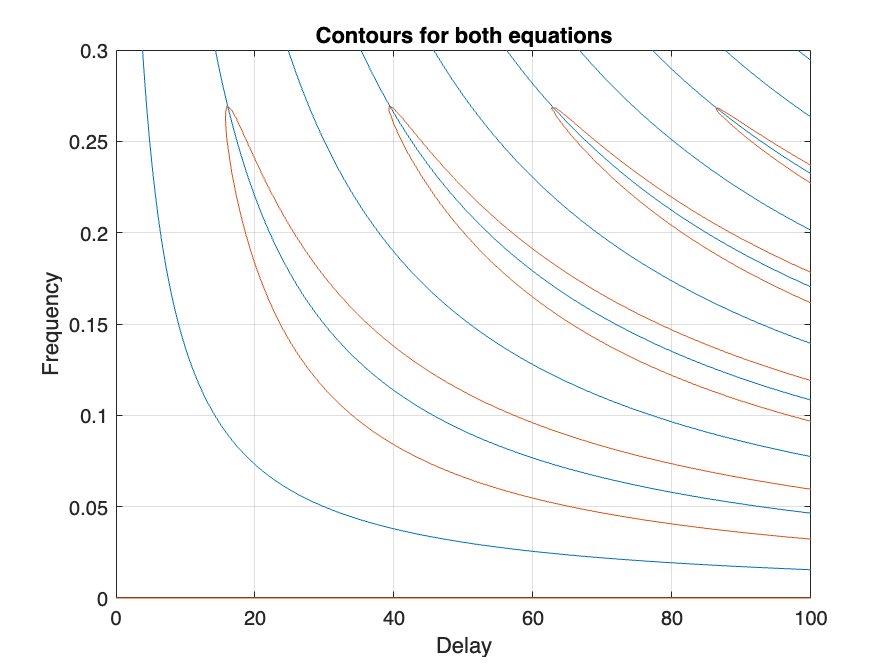

F1 = @(t,w) a*d*cos(t.*w)+(2*(a*c-b*d)*w.*sin(t.*w))/b;
F2 = @(t,w) (2*(a*c-b*d)*w.*cos(t.*w))/b+d*(2*w-(2*b*w)/c-a*sin(t.*w));

dom = 100;
height = 0.3;
fimplicit(F1,[0 dom 0 height])
hold on
fimplicit(F2, [0 dom 0 height])
hold off
grid
xlabel("Delay")
ylabel("Frequency")
title("Contours for both equations")

It appears that both contours cross at around $\tau=20$, but the model collapse is happening much before. This can be due to the higher order terms in the Taylor being truncated, an aproximation only valid for small perturbation around equilibrium. Therefore, this supposition will be tested by taking a sinusoidal perturbation around equilibrium.

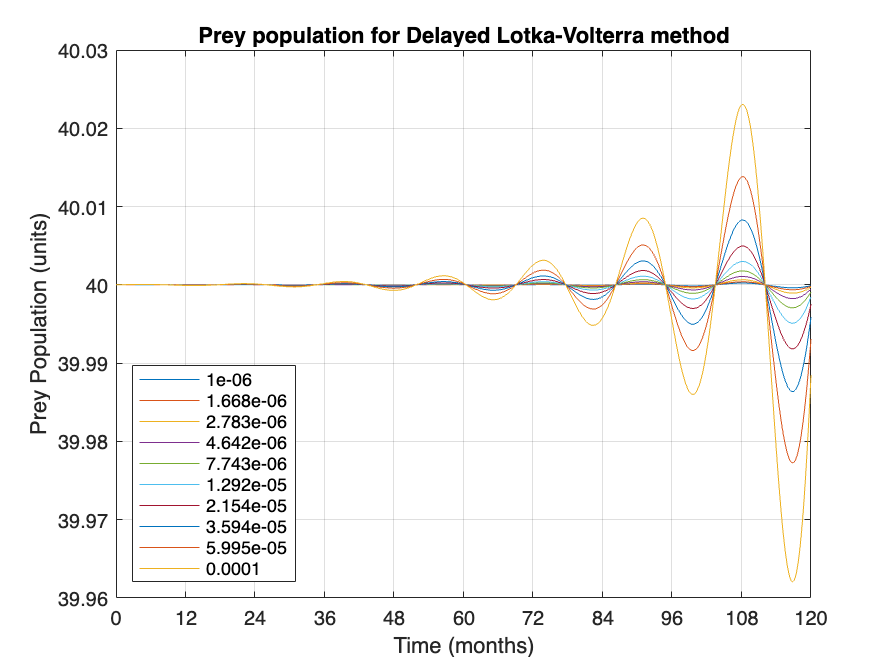

a = 0.5; b = 0.02; c = 0.01; d = 0.4;

prey = d/c; predator = a/b; n = 1000; t_end = 120; tau = 1;

f = DelayedLotkaVolterra(a,b,c,d);

perturbation = logspace(-6,-4,10);
P = []; % Prey
Z = []; % Predator

for i=1:10
    epsilon = perturbation(i);
    phi = @(t) [prey; predator] + epsilon*sin(t);
    [t, x] = StepsMethod(f,0,t_end,@DormandPrince,tau,phi,n);
    P = [P x(:,1)];
    Z = [Z x(:,2)];
end

figure()
plot(t,P)
grid

legend(string(round(perturbation,4,"significant")),location="southwest")
title("Prey population for Delayed Lotka-Volterra model")
xlim([0 t_end])

xticks(0:12:t_end)
ylabel("Prey Population (units)")
xlabel("Time (months)")

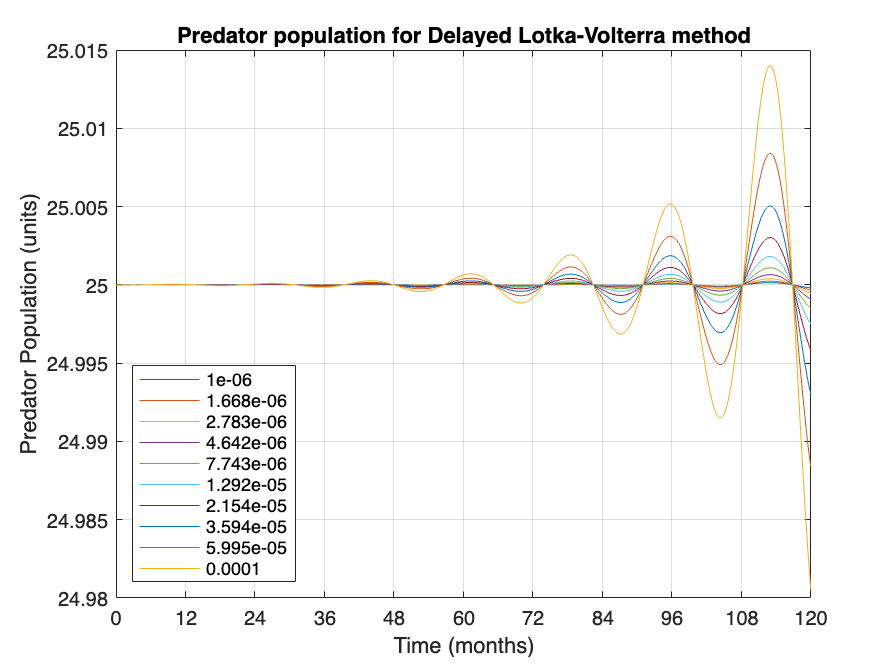


plot(t,Z)
grid

legend(string(round(perturbation,4,"significant")),location="southwest")
title("Predator population for Delayed Lotka-Volterra model")
xlim([0 t_end])

xticks(0:12:t_end)
ylabel("Predator Population (units)")
xlabel("Time (months)")

It can be seen that perturbations cause exponentially growing oscillations, even for relatively low initial perturbations. This might suggest the model is inconditionally unstable.

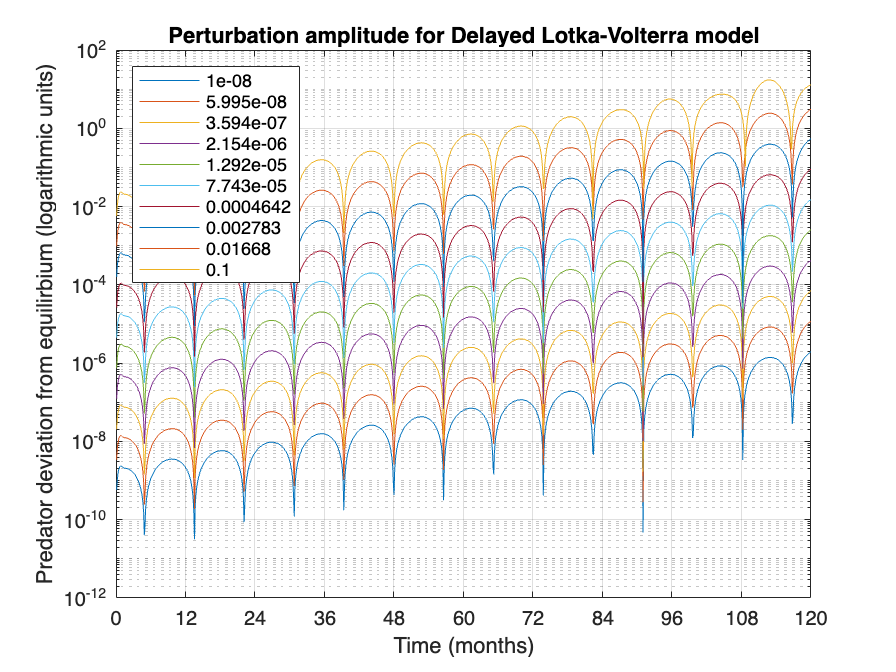

perturbation = logspace(-8,-1,10);
P = []; % Prey
Z = []; % Predator

for i=1:10
    epsilon = perturbation(i);
    phi = @(t) [prey; predator] + epsilon*sin(t);
    [t, x] = StepsMethod(f,0,t_end,@DormandPrince,tau,phi,n);
    P = [P x(:,1)];
    Z = [Z x(:,2)];
end

figure()
semilogy(t,abs(Z-predator))
grid

legend(string(round(perturbation,4,"significant")),location="northwest")
title("Perturbation amplitude for Delayed Lotka-Volterra model")
xlim([0 t_end])

xticks(0:12:t_end)
ylabel("Predator deviation from equilirbium (logarithmic units)")
xlabel("Time (months)")

By plotting the logarithmic deviation from the equilibrium, it can be seen how the oscillations grow linearly, showing that regardless of the initial perturbation, the resulting effect will be exponentially growing oscillations until numerical collapse. This makes sense, as the LotkaVolterra is neutrally stable, so any phase lag introduced by the delay won't be damped, always leading to growing oscillations.